# Control Continuo LQR para Ball&Plate 

Universidad de Nariño

**Ventajas**

- **Optimización explícita:** Minimiza una función de costo cuadrática específica.

- **Rendimiento óptimo:** Proporciona un rendimiento óptimo para el sistema linealizado.

**Desventajas**

- **Complejidad de diseño:** Requiere la selección adecuada de matrices de peso al ojímetro.

- **Sensibilidad a incertidumbres:** Puede ser menos robusto ante variaciones de los parámetros del sistema.

#### 
$$\begin{array}{l}
x_1 :\textrm{posición}\;\textrm{eje}\;X\\
x_2 :\textrm{posición}\;\textrm{eje}\;Y\\
x_3 :\textrm{velocidad}\;\textrm{eje}\;X\\
x_4 :\textrm{velocidad}\;\textrm{eje}\;Y
\end{array}$$


#### Simbolicos

clear; close all; clc;
sympref('FloatingPointOutput',true);
syms Mv L m R Iv Ib g       %%% Parametros
syms a b               %%% Parametros Auxiliares
syms x x_dot_ f Xss [4,1]   %%% Estados, Campos Vectoriales 
syms u Uss U_dot_x U_x U_y U_dot_y                 %%% Entradas
syms r1                     %%% Referencia 
syms den(x1)

### Modelo del Sistema

%%% Sistema NO Lineal
f(1) = x(2);
f(2) = a*(x(1)*U_dot_x^2+x(3)*U_dot_x*U_dot_y-g*sin(U_x));
f(3) = x(4);
f(4) = a*(x(3)*U_dot_y^2+x(1)*U_dot_x*U_dot_y-g*sin(U_y));
sys = (x_dot_ == f)

$$sys = \left(\begin{array}{c} {\dot{x}}_{1}=x_{2}\\ {\dot{x}}_{2}=a\,\left(x_{1}\,{{\dot{U}}_{x}}^{2}+{\dot{U}}_{y}\,x_{3}\,{\dot{U}}_{x}-g\,\sin\left(U_{x}\right)\right)\\ {\dot{x}}_{3}=x_{4}\\ {\dot{x}}_{4}=a\,\left(x_{3}\,{{\dot{U}}_{y}}^{2}+{\dot{U}}_{x}\,x_{1}\,{\dot{U}}_{y}-g\,\sin\left(U_{y}\right)\right) \end{array}\right)$$

### Sistema Linealizado Simbólico.

syms x1 x2 x3 x4 U_dot_x U_dot_y U_x U_y a g
% Sistema de ecuaciones
fsim = [x2; 
    a*(x1*U_dot_x^2 + x3*U_dot_x*U_dot_y - g*sin(U_x));
    x4; 
    a*(x3*U_dot_y^2 + x1*U_dot_x*U_dot_y - g*sin(U_y))];

% Teniendo encuenta las derivadas:
sys = [diff(x1) == fsim(1);
       diff(x2) == fsim(2);
       diff(x3) == fsim(3);
       diff(x4) == fsim(4)];
%diff() -> derivada.

% Sustitución punto de origen:
A_origen = subs(sys, [x1, x2, x3, x4], [0, 0, 0, 0]);
B_origen = subs(sys, [x1, x2, x3, x4], [0, 0, 0, 0]);

% Calcula jacobianos:
A_syms = jacobian(f, [x1, x2, x3, x4]);
B_syms = jacobian(f, [U_dot_x, U_dot_y, U_x, U_y]);

% Sustitución punto de origen:
A_origen = subs(A_syms, [x1, x2, x3, x4, U_dot_x, U_dot_y, U_x, U_y], [0, 0, 0, 0, 0, 0, 0, 0]);
B_origen = subs(B_syms, [x1, x2, x3, x4, U_dot_x, U_dot_y, U_x, U_y], [0, 0, 0, 0, 0, 0, 0, 0]);

disp('A para Linealización del sistema para punto de origen (0 0 0 0):');

A para Linealización del sistema para punto de origen (0 0 0 0):


disp(A_origen);

$$\left(\begin{array}{cccc} 0 & 1 & 0 & 0\\ 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 1\\ 0 & 0 & 0 & 0 \end{array}\right)$$

disp('B para Linealización del sistema para punto de origen (0 0 0 0):');

B para Linealización del sistema para punto de origen (0 0 0 0):


disp(B_origen);

$$\left(\begin{array}{cccc} 0 & 0 & 0 & 0\\ 0 & 0 & -a\,g & 0\\ 0 & 0 & 0 & 0\\ 0 & 0 & 0 & -a\,g \end{array}\right)$$

#### Parámetros

%%%% Parametros
a=5/7; g=9.8; kbb=-a*g;
% r1=0.05; r2=0.1;

%%%% Variables Auxiliares
% kbb=5*g*r_arm/(7*L_beam);

#### Matrices del sistema lineal en continuo.

%========= Matrices del sistema lineal en continuo===================
disp("Matrices Linealizadas: ")

Matrices Linealizadas: 


A1=[0 1;0 0];
B1=[0;-a*g];
C1=[1 0];
D1=0;

A2=[0 1;0 0];
B2=[0;-a*g];
C2=[1 0];
D2=0;       

Sys1c=ss(A1,B1,C1,D1)

Sys1c =
 
  A = 
       x1  x2
   x1   0   1
   x2   0   0
 
  B = 
       u1
   x1   0
   x2  -7
 
  C = 
       x1  x2
   y1   1   0
 
  D = 
       u1
   y1   0
 
Continuous-time state-space model.
<a href="matlab:disp(char('','                A: [2×2 double] ','                B: [2×1 double] ','                C: [1 0] ','                D: 0 ','                E: [] ','          Offsets: [] ','           Scaled: 0 ','        StateName: {2×1 cell} ','        StatePath: {2×1 cell} ','        StateUnit: {2×1 cell} ','    InternalDelay: [0×1 double] ','       InputDelay: 0 ','      OutputDelay: 0 ','        InputName: {''''} ','        InputUnit: {''''} ','       InputGroup: [1×1 struct] ','       OutputName: {''''} ','       OutputUnit: {''''} ','      OutputGroup: [1×1 struct] ','            Notes: [0×1 string] ','         UserData: [] ','             Name: '''' ','               Ts: 0 ','         TimeUnit: ''seconds'' ','     SamplingGrid: [1×1 struct] ',' '))">Model Properties</a

Sys2c=ss(A2,B2,C2,D2)

Sys2c =
 
  A = 
       x1  x2
   x1   0   1
   x2   0   0
 
  B = 
       u1
   x1   0
   x2  -7
 
  C = 
       x1  x2
   y1   1   0
 
  D = 
       u1
   y1   0
 
Continuous-time state-space model.
<a href="matlab:disp(char('','                A: [2×2 double] ','                B: [2×1 double] ','                C: [1 0] ','                D: 0 ','                E: [] ','          Offsets: [] ','           Scaled: 0 ','        StateName: {2×1 cell} ','        StatePath: {2×1 cell} ','        StateUnit: {2×1 cell} ','    InternalDelay: [0×1 double] ','       InputDelay: 0 ','      OutputDelay: 0 ','        InputName: {''''} ','        InputUnit: {''''} ','       InputGroup: [1×1 struct] ','       OutputName: {''''} ','       OutputUnit: {''''} ','      OutputGroup: [1×1 struct] ','            Notes: [0×1 string] ','         UserData: [] ','             Name: '''' ','               Ts: 0 ','         TimeUnit: ''seconds'' ','     SamplingGrid: [1×1 struct] ',' '))">Model Properties</a


%%% Sistema Ampliado
A1a = [A1 zeros(2,1); -C1 0] 

A1a =      0     1     0
     0     0     0
    -1     0     0


B1a = [B1; 0]

B1a =          0
   -7.0000
         0



A2a = [A2 zeros(2,1); -C2 0]

A2a =      0     1     0
     0     0     0
    -1     0     0


B2a = [B2; 0]

B2a =          0
   -7.0000
         0



% %%% Controlabilidad
 %Ct=[B1 A1*B1]; rank(Ct)
 %sym(Ct)
 %det(Ct)
%{
Ct=ctrb(A,B)
ran_con=rank(Ct)
if ran_con==size(A,1)
    disp("Sistema controlable")
else
    disp("Sistema No controlable")
end
%}

## Diseño del controlador

%%% StateFB Con Integrador
    %%% Ubicacion de polos Besel
    % polos=[-3.967-3.785*1j, -3.967+3.785*1j, -5.009*-0.1]  % Polos Bessel 3 Mod
    % polos=[-3.967+3.785*1j*0, -3.967-3.785*1j*0, -5.009*0.05]*2  % Polos Bessel 3 Mod
    % polosdg=exp(polos*Ts)
    % Ka=acker(Aa,Ba,polosdg/1)

    %%% Ubicacion de Polos LQR
    Q1a=diag([3 1 1]) % Q1a=diag([1 500 0.1]) pesos: [posición, velocidad, integral]

Q1a =      3     0     0
     0     1     0
     0     0     1


    R1=500 %100

R1 = 500

    K1a=lqr(A1a,B1a,Q1a,R1)

K1a =    -0.1598   -0.2183    0.0447



    Q2a=diag([3 1 1]) % Q2a=diag([1 500 0.1])

Q2a =      3     0     0
     0     1     0
     0     0     1


    R2=500 %100

R2 = 500

    K2a=lqr(A2a,B2a,Q2a,R2)

K2a =    -0.1598   -0.2183    0.0447


    disp("Si R > Q, da regulación lenta.")

Si R > Q, da regulación lenta.



% Sys1K=ss(A1a-B1a*K1a,B1a,[C1 0],D1); [p,~]=pzmap(Sys1K); zplane([],p);zgrid(Ts);

## Implementación de control con simulación ODE

Condiciones iniciales y periodo de muestreo

Tsim=120;            % Tiempo total de la simulación
Ts=0.15;            % Periodo de muestreo
Ns=round(Tsim/Ts);  % Número de periodos de muestreo que tendrá la simulación.
x_01=[0 0 0 0]';    % Condiciones Inciales [pos, vel]
u1_ant=0; u2_ant=0; 
u1=0; u2=0;         % Señal de control para el primer instante de muestreo.
int_err1=0; int_err2=0;
x=zeros(Ns,4); usim=zeros(Ns,2); % Tamaño de vectores definido

ref1=0.1; ref2=0.1;

e_ans1=0; e_ans2=0;

### Ciclo de simulación


for k=1:Ns
    du1=(u1-u1_ant);     du2=(u2-u2_ant);
    u1_ant=u1;              u2_ant=u2;
    [~,xd]=ode23s('plantabp',Ts,x_01,[],u1,du1,u2,du2);   % Simular la planta para un Ts.
    xmed=xd(end,:)'; % Medir estados (la última señal se toma a los Ts segundos).
    %%% State Feedback Control
    e_act1=(ref1-xmed(1)); e_act2=(ref2-xmed(3));  % Cálculo del error
    int_err1=int_err1+((e_act1+e_ans1)*Ts)/2; int_err2=int_err2+((e_act2+e_ans2)*Ts)/2;  % Integrador 
    u1=-(dot(K1a(1:2),xmed(1:2)))-K1a(end)*int_err1; % Señal de control u=-Kx-Ki*integralError
    u2=-(dot(K2a(1:2),xmed(3:4)))-K2a(end)*int_err2; % Señal de control u=-Kx-Ki*integralError
    % u=-Kx-Ki*integralError. para compactar dos valores usamos dot(K2a(1:2),xmed(3:4)).

    %%% Actualiza Variables y guarda para graficar
    e_ans1=e_act1; e_ans2=e_act2;
    
    x_01=xmed; x(k,:)=xmed'; usim(k,:)=[u1 u2]; 
    %Referencia Fija:
    %ref1=-ref1; ref2;
  
    %% Cambia Referencias
    if k==round(Ns/5)
        ref1=-ref1; ref2;
    end
    if k==round(2*Ns/5)
        ref1; ref2=-ref2;
    end
    if k==round(3*Ns/5)
        ref1=-ref1; ref2;
    end
    if k==round(4*Ns/5)
        ref1; ref2=-ref2;
    end
    
end

## Graficación

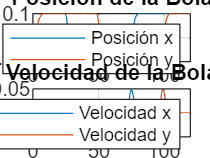

tdisc=0:Ts:Ns*Ts-Ts;
figure; subplot(2,1,1); plot(tdisc,[x(:,1) x(:,3)]); title('Posición de la Bola');
xlabel('Tiempo (s)'); ylabel({'Estados del sistema','[m,m/s]'});
legend('Posición x','Posición y')
grid on;
subplot(2,1,2); plot(tdisc,[x(:,2) x(:,4)]); title('Velocidad de la Bola');
xlabel('Tiempo (s)'); ylabel({'Ángulo del motor','[grados]'});
legend('Velocidad x','Velocidad y')
grid on;

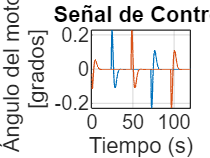


figure
plot(tdisc,usim*180/pi); title('Señal de Control');
xlabel('Tiempo (s)'); ylabel({'Ángulo del motor','[grados]'});
grid on;

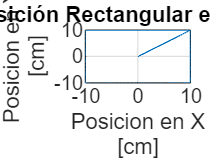


figure;
plot(x(:,1)*100,x(:,3)*100);title('Posición Rectangular en el Plato');
xlabel({'Posicion en X','[cm]'}); ylabel({'Posicion en Y','[cm]'});
%xlim([-22.5/2 22.5/2]); ylim([-22.5/2 22.5/2]); 
grid on;


%{
%%% Indices de desempeño (ITAE)
t = tdisc;
r = ref1(1)*ones(size(t));
% y = -1*(x(:,1)'-x(1,1));      % ref<x_0
y = x(:,1)';                    % ref>x_0

% ise = sum((r-y).^2)*Ts;         % ISE
% itse = sum(t.*(r-y).^2)*Ts;     % ITSE
% iae = sum(abs(r - y))*Ts;       % IAE
% itae = sum(t.*abs(r - y))*Ts;   % ITAE

If = stepinfo(y,t);             % Tes,Ovs

fprintf('\n\n\n Indices de Desempeño \n');
% fprintf('   ISE: %f \n',ise);
% fprintf('   ITSE: %f \n',itse);
% fprintf('   IAE: %f \n',iae);
% fprintf('   ITAE: %f \n',itae);
fprintf(' Tiempo de Establecimiento: %f segundos \n',If.SettlingTime);
fprintf(' Sobre Paso: %f%% \n\n',If.Overshoot);

x_mat= x; u_mat=usim;
%}

# Control para Referencia Simple.

Tsim=60;            % Tiempo total de la simulación
Ts=0.15;            % Periodo de muestreo
Ns=round(Tsim/Ts);  % Número de periodos de muestreo que tendrá la simulación.
x_01=[0 0 0 0]';    % Condiciones Inciales [pos, vel]
u1_ant=0; u2_ant=0; 
u1=0; u2=0;         % Señal de control para el primer instante de muestreo.
int_err1=0; int_err2=0;
x=zeros(Ns,4); usim=zeros(Ns,2); % Tamaño de vectores definido

ref1=0.1; ref2=0.1; % metros, 0.2=20cm. ++++++++++++++++++++++

e_ans1=0; e_ans2=0;

for k=1:Ns
    du1=(u1-u1_ant);     du2=(u2-u2_ant);
    u1_ant=u1;              u2_ant=u2;
    [~,xd]=ode23s('plantabp',Ts,x_01,[],u1,du1,u2,du2);   % Simular la planta para un Ts.
    xmed=xd(end,:)'; % Medir estados (la última señal se toma a los Ts segundos).
    %%% State Feedback Control
    e_act1=(ref1-xmed(1)); e_act2=(ref2-xmed(3));  % Cálculo del error
    int_err1=int_err1+((e_act1+e_ans1)*Ts)/2; int_err2=int_err2+((e_act2+e_ans2)*Ts)/2;  % Integrador 
    u1=-(dot(K1a(1:2),xmed(1:2)))-K1a(end)*int_err1; % Señal de control u=-Kx-Ki*integralError
    u2=-(dot(K2a(1:2),xmed(3:4)))-K2a(end)*int_err2; % Señal de control u=-Kx-Ki*integralError
    % u=-Kx-Ki*integralError. para compactar dos valores usamos dot(K2a(1:2),xmed(3:4)).

    %%% Actualiza Variables y guarda para graficar
    e_ans1=e_act1; e_ans2=e_act2;
    
    x_01=xmed; x(k,:)=xmed'; usim(k,:)=[u1 u2]; 
 
    
end

## Graficación referencia simple.

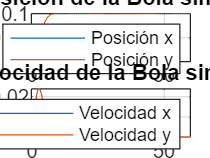

tdisc=0:Ts:Ns*Ts-Ts;
figure; subplot(2,1,1); plot(tdisc,[x(:,1) x(:,3)]); title('Posición de la Bola simple');
xlabel('Tiempo (s)'); ylabel({'Estados del sistema','[m,m/s]'});
legend('Posición x','Posición y')
grid on;
subplot(2,1,2); plot(tdisc,[x(:,2) x(:,4)]); title('Velocidad de la Bola simple');
xlabel('Tiempo (s)'); ylabel({'Ángulo del motor','[grados]'});
legend('Velocidad x','Velocidad y')
grid on;

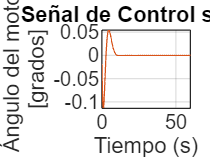


figure
plot(tdisc,usim*180/pi); title('Señal de Control simple');
xlabel('Tiempo (s)'); ylabel({'Ángulo del motor','[grados]'});
grid on;

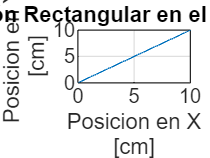


figure;
plot(x(:,1)*100,x(:,3)*100);title('Posición Rectangular en el Plato simple');
xlabel({'Posicion en X','[cm]'}); ylabel({'Posicion en Y','[cm]'});
%xlim([-22.5/2 22.5/2]); ylim([-22.5/2 22.5/2]); 
grid on;


%%% Indices de desempeño (ITAE)
t = tdisc;
r = ref1(1)*ones(size(t));
% y = -1*(x(:,1)'-x(1,1));      % ref<x_0
y = x(:,1)';                    % ref>x_0

% ise = sum((r-y).^2)*Ts;         % ISE
% itse = sum(t.*(r-y).^2)*Ts;     % ITSE
% iae = sum(abs(r - y))*Ts;       % IAE
itae = sum(t.*abs(r - y))*Ts;   % ITAE

If = stepinfo(y,t);             % Tes,Ovs

%fprintf('\n\n\n Indices de Desempeño\n');
% fprintf('   ISE: %f \n',ise);
% fprintf('   ITSE: %f \n',itse);
% fprintf('   IAE: %f \n',iae);
fprintf('\n\n\n Indices de Desempeño LQR\n');




 Indices de Desempeño LQR


fprintf('   ITAE: %f \n',itae);

   ITAE: 0.761295 


fprintf(' Tiempo de Establecimiento: %f segundos \n',If.SettlingTime);

 Tiempo de Establecimiento: 7.371715 segundos 


fprintf(' Sobre Paso: %f%% \n\n',If.Overshoot);

 Sobre Paso: 0.000000% 




x_mat= x; u_mat=usim;

